# Control a Simulink Simulation with App Designer

This example shows how to create an interface to control a simulation for a Simulink® model. The app demonstrates connecting UI components to model elements by creating bindings and by writing callbacks to set model parameters.

## Open the Model

 This example uses a model of a mass-spring-damper. The Simulink model uses signal connections, which define how data flows from one block to another. 

open_system('ex_mass_spring_damper_appdemo')

## Open and Examine the App

Open the `controlSimulations.mlapp` in App Designer. The app provides a user interface to interact with the `ex_mass_spring_damper_appdemo` model. You can run the model, view the elapsed time, change the model stop time, and tune a model variable from within the app. The app contains some Simulink UI components, and some common App Designer components. You can connect some of these components with certain variables and signals in the model. Connecting the signals and variables in the model with the UI components allows you to visualize the signal, as well as control the values for the simulation from your app. 

open('controlSimulations.mlapp')

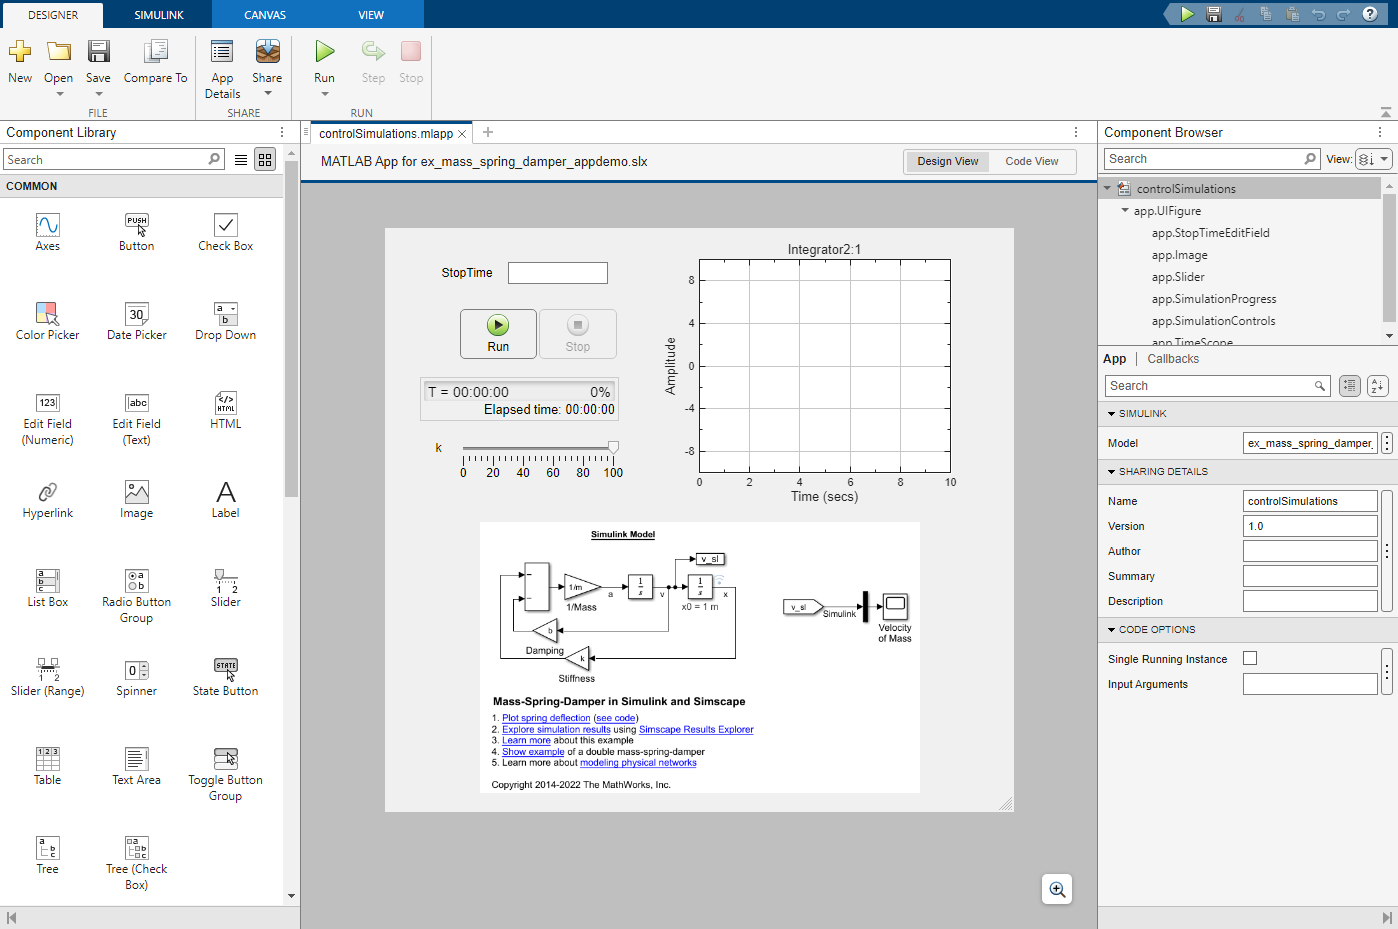

The `controlSimulations` app contains the following UI components:

- Simulation Controls (Simulink section) -  start, pause, and stop the simulation of the model. 

- Simulation Progress (Simulink section) - monitor the progress of the simulation, as well as simulation time, and elapsed time.

- Time Scope (Simulink section) -  display time domain signals in the app. You can connect this UI component with a logged signal in the Simulink model. 

- Stop Time Edit Field (Common section) - specify simulation stop time.

- Slider (Common section) - specify a value for a tunable variable that it is connected with. You can also specify the range of values.

- Image (Common section) - display a model image.

### Control Simulations Using UI Components

This example connects UI components in the app to elements of the model using these techniques:

-  Connecting the time scope to the Integrator signal by creating a binding.

-  Connecting the slider to the Stiffness variable by creating a binding.

-  Connecting the edit field to the simulation stop time by creating a callback that updates the `StopTime` model parameter of the `Simulation` object associated with the app.

To learn how to bind UI components to elements, see [Connect UI Components to Simulink Model Elements](docid:simulink_ug#mw_32ff77af-6950-4e6a-96fb-384369cf6fc9).

The Stop Time Edit Field is not a Simulink UI component. It is a standard UI component that is configured programmatically to set the `StopTime` model parameter. You can programmatically configure the [`Simulation`](docid:simulink_ref#mw_1ecc65e1-5a93-41d6-94ac-2f7145d68206) object by using the `Simulation` app property. The `StopTime` edit field is attached to the model parameter `StopTime` using a callback function. Click on the StopTime edit field in App Designer. To see the callbacks for the `StopTime` component, click `StopTimeEditFieldValueChangedFcn`. To examine this function, click the `StopTime` field and go to Code View. In the Code View, you can see the callback function `StopTimeEditFieldValueChangedFcn`.

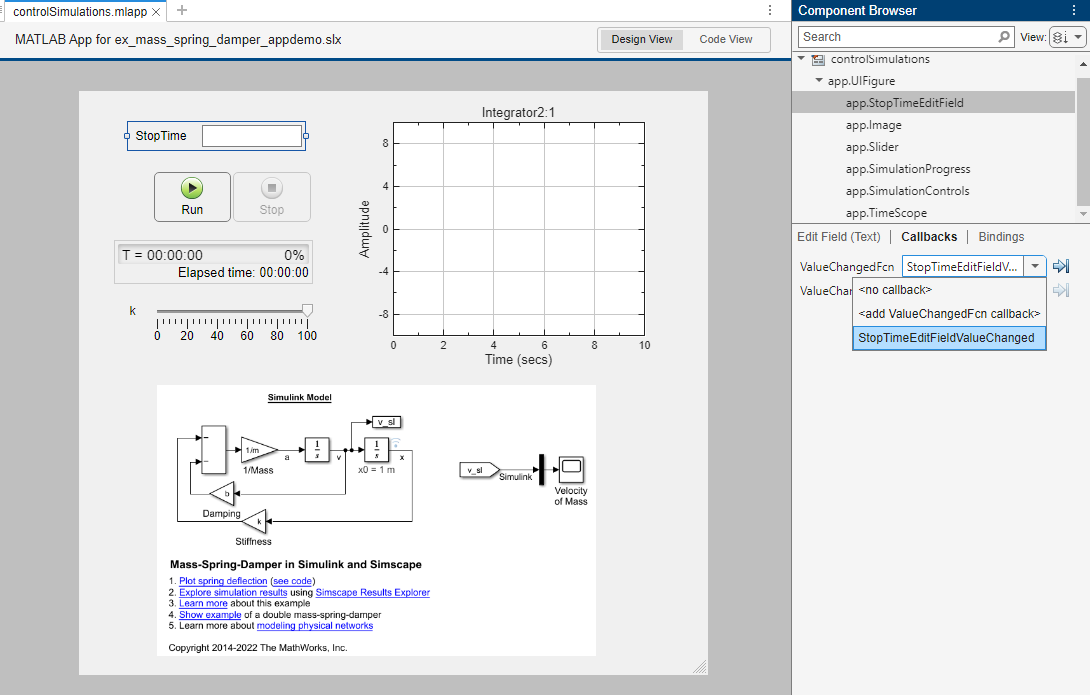

## Run the App

Once your app is modified as per your needs, and the binding of the UI components and the model elements is complete, you can run the app. Click Run on the toolstrip. Now, the app is ready to be used.

Click Run on the app. You can see the signal, `Integrator` for the selected value of `Stiffness`. Now you can easily change the value of the variable `Stiffness`, and run the simulation again to observe how the signal `Integrator` changes with different values of `Stiffness`. 

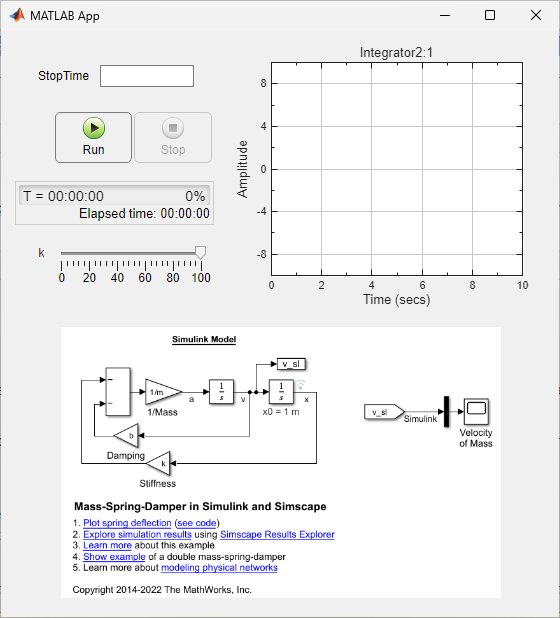

*Copyright 2024 The MathWorks, Inc.*